# Fitting a Circle

Load the data:

load('circ.mat')

Solve the least square problem $V \mathbf{c} = \mathbf{b}$ using backslash:

V = [2*x 2*y ones(size(x))];
b = x.^2 + y.^2;
c = V\b;
r = sqrt(c(1)^2+c(2)^2+c(3));

Plot the data and the fitting function (expressed as parametric equations)

$x = c_1 + r \cos(\theta), \quad y = c_2 + r \sin(\theta),$  for $\theta \in [0, 2\pi]$.

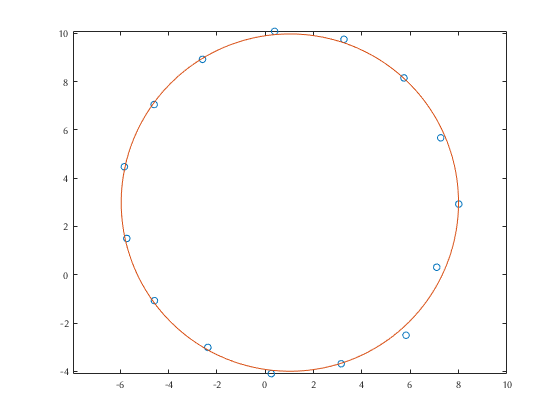

theta = linspace(0, 2*pi, 361);
xplt = c(1) + r*cos(theta);
yplt = c(2) + r*sin(theta);
clf
plot(x, y, 'o', xplt, yplt)
axis equal